%% =============================================================
%  CP-PLL Complete Analysis — LTspice Matched Parameters
%  
%  Merged script: ideal loop analysis + phase noise, single parameter set.
%  TSMC 0.18um CMOS, LC cross-coupled VCO, 6.25 GHz output.
%
%  Figures (8 total):
%    Fig 1 — Open-loop Bode L(s) with fz/fp/fu/PM
%    Fig 2 — Closed-loop tracking vs error rejection
%    Fig 3 — Phase step responses (Href + Herr)
%    Fig 4 — Frequency step response (Dfout + DVctrl)
%    Fig 5 — Noise transfer functions
%    Fig 6 — Output PN PSD + improvement vs free VCO
%    Fig 7 — Per-source noise shaping (4 panels)
%    Fig 8 — Piecewise capture model Vctrl(t)
% =============================================================
clear; clc; close all;

%% =====================================================================
%  1. PARAMETERS (LTspice-Matched)
%% =====================================================================
fref = 781.25e6;              % reference clock, Hz
N    = 8;                     % division ratio
Icp  = 10e-6;                 % charge pump current, A
Kpd  = Icp/(2*pi);            % PFD/CP gain, A/rad
Kvco = 2*pi*540e6;            % |Kvco| at lock point, rad/(s*V)
R1   = 500;                   % loop filter R, Ohm
C1   = 50e-12;                % C1, F
C2   = 5e-12;                 % C2, F
fout = fref * N;              % output freq, Hz (6.25 GHz)

fprintf('=== LTspice-Matched PLL Parameters ===\n');

=== LTspice-Matched PLL Parameters ===


fprintf('fref = %.2f MHz,  N = %d,  fout = %.3f GHz\n', fref/1e6, N, fout/1e9);

fref = 781.25 MHz,  N = 8,  fout = 6.250 GHz


fprintf('Icp = %.1f uA,  Kpd = %.3f uA/rad\n', Icp*1e6, Kpd*1e6);

Icp = 10.0 uA,  Kpd = 1.592 uA/rad


fprintf('Kvco = %.0f MHz/V\n', Kvco/(2*pi*1e6));

Kvco = 540 MHz/V


fprintf('R1 = %.0f Ohm,  C1 = %.0f pF,  C2 = %.0f pF,  C1/C2 = %.0f\n', ...
        R1, C1*1e12, C2*1e12, C1/C2);

R1 = 500 Ohm,  C1 = 50 pF,  C2 = 5 pF,  C1/C2 = 10



%% =====================================================================
%  2. FREQUENCY GRID + CONSTANTS
%% =====================================================================
f = logspace(log10(1e3), log10(5e9), 2000);
w = 2*pi*f;

q  = 1.602e-19;
kB = 1.38e-23;
T  = 300;

%% =====================================================================
%  3. LOOP TRANSFER FUNCTIONS (computed once, used by both analyses)
%% =====================================================================

% Loop filter transimpedance Z(jw)
Zw = (1 + 1i*w*R1*C1) ./ ((1i*w).^2 * R1*C1*C2 + 1i*w*(C1 + C2));

% Forward gain, open-loop, closed-loop
Aw   = Kpd .* Zw .* Kvco ./ (1i*w);
Gw   = Aw / N;                          % open-loop L(jw)
Hw   = Aw ./ (1 + Aw/N);               % theta_out / theta_in (DC = N)
Hdiv = Hw / N;                           % theta_div / theta_in (DC = 1)
Herr_w = 1 - Hdiv;                       % phase error TF

% Noise transfer functions
Pw     = Hw ./ Kpd;                      % CP current -> out
Lnode  = Hw ./ (Kpd .* Zw);             % filter voltage -> out
Ew     = Hw .* 1i.*w ./ (Kpd*Kvco.*Zw); % VCO phase -> out

% Loop metrics
[~, idx_u] = min(abs(abs(Gw) - 1));
fu = f(idx_u);
fz = 1/(2*pi*R1*C1);
fp = (C1+C2)/(2*pi*R1*C1*C2);
PM_approx = (atan(fu/fz) - atan(fu/fp)) / pi * 180;

wc_formula = Icp * Kvco * R1 / N;
fc_formula = wc_formula / (2*pi);

fprintf('\n=== Loop Metrics ===\n');


=== Loop Metrics ===


fprintf('Zero fz = %.3f MHz,  Pole fp = %.1f MHz\n', fz/1e6, fp/1e6);

Zero fz = 6.366 MHz,  Pole fp = 70.0 MHz


fprintf('Unity-gain fu = %.3f kHz  (numerical)\n', fu/1e3);

Unity-gain fu = 559.695 kHz  (numerical)


fprintf('Crossover fc  = %.3f kHz  (formula)\n', fc_formula/1e3);

Crossover fc  = 337.500 kHz  (formula)


fprintf('Phase margin  = %.1f deg\n', PM_approx);

Phase margin  = 4.6 deg



% tf objects (for Bode, step, lsim)
s = tf('s');
F_tf    = (1 + s*R1*C1) / (s^2*R1*C1*C2 + s*(C1+C2));
A_tf    = Kpd * F_tf * Kvco / s;
L_tf    = A_tf / N;
Href_tf = A_tf / (1 + A_tf/N);
Hdiv_tf = L_tf / (1 + L_tf);
Herr_tf = 1 - Hdiv_tf;

[GM, PM_exact, Wcg, Wcp] = margin(L_tf);
fu_exact = Wcp / (2*pi);

fprintf('Phase margin (exact) = %.2f deg at fu = %.3f kHz\n', PM_exact, fu_exact/1e3);

Phase margin (exact) = 4.56 deg at fu = 558.634 kHz



%% =====================================================================
%  4. NOISE MODELS (physics-based, scaled for 6.25 GHz)
%% =====================================================================

% Reference: RF-grade source at 781.25 MHz (not a crystal)
PN_ref_anchor = -120;  f_ref_anchor = 10e3;  ref_slope = -20;  PN_ref_floor = -160;
PN_ref = max(PN_ref_anchor + ref_slope*log10(f/f_ref_anchor), PN_ref_floor);

% VCO: 6.25 GHz LC-VCO, 0.18um CMOS (Leeson model)
% Three-region: 1/f^3 + 1/f^2 + floor
PN_vco_anchor = -85;           % dBc/Hz at 100 kHz (in 1/f^2 region)
f_vco_anchor  = 100e3;
f_1f_corner   = 50e3;          % flicker corner (higher for GHz CMOS VCO)
PN_vco_floor  = -150;          % dBc/Hz thermal floor

PN_vco_base    = PN_vco_anchor - 20*log10(f / f_vco_anchor);
PN_vco_flicker = PN_vco_base + 10*log10(max(f_1f_corner ./ f, 1));
PN_vco         = max(PN_vco_flicker, PN_vco_floor);

% CP: shot noise S_i = 4qIcp
S_icp = 4 * q * Icp;
PN_pc = 10*log10(S_icp) * ones(size(f));

% LPF: thermal noise S_v = 4kTR1
S_v_R1 = 4 * kB * T * R1;
PN_lpf = 10*log10(S_v_R1) * ones(size(f));

fprintf('\n=== Noise Sources ===\n');


=== Noise Sources ===


fprintf('Ref:  %.0f dBc/Hz @ %.0f kHz, slope %.0f dB/dec\n', PN_ref_anchor, f_ref_anchor/1e3, ref_slope);

Ref:  -120 dBc/Hz @ 10 kHz, slope -20 dB/dec


fprintf('VCO:  %.0f dBc/Hz @ %.0f kHz, Leeson 1/f corner = %.0f kHz\n', PN_vco_anchor, f_vco_anchor/1e3, f_1f_corner/1e3);

VCO:  -85 dBc/Hz @ 100 kHz, Leeson 1/f corner = 50 kHz


fprintf('CP:   S_icp = %.2e A^2/Hz (%.1f dB)\n', S_icp, 10*log10(S_icp));

CP:   S_icp = 6.41e-24 A^2/Hz (-231.9 dB)


fprintf('LPF:  S_v = %.2e V^2/Hz (%.1f dB)\n', S_v_R1, 10*log10(S_v_R1));

LPF:  S_v = 8.28e-18 V^2/Hz (-170.8 dB)



%% =====================================================================
%  5. NOISE PROPAGATION + TOTAL (with Task 6 CP calibration)
%% =====================================================================
PN_out_ref = PN_ref + 20*log10(abs(Hw));
PN_out_pc  = PN_pc  + 20*log10(abs(Pw));
PN_out_lpf = PN_lpf + 20*log10(abs(Lnode));
PN_out_vco = PN_vco + 20*log10(abs(Ew));

% --- [Task 6] CP Noise Flicker Calibration from LTspice .noise -------------
%  Replace flat shot-noise CP model with LTspice-calibrated data.
%  LTspice .noise gives CLOSED-LOOP output contributions (not source PSD).
%  Data points: M_bn2 + M9 flicker noise dominant (97% of CP noise power).

% Jitter integration index (needed here for pre/post comparison)
f_jitter_min = 1e3;
f_jitter_max = fout/2;
idx_jit = (f >= f_jitter_min) & (f <= f_jitter_max);

% Save original shot-noise model for comparison
PN_out_pc_shot = PN_out_pc;

% Pre-calibration total (for jitter comparison later)
PN_out_preCAL = 10*log10(10.^(PN_out_ref/10) + 10.^(PN_out_pc_shot/10) + ...
                         10.^(PN_out_lpf/10) + 10.^(PN_out_vco/10));
PN_int_pre = trapz(f(idx_jit), 10.^(PN_out_preCAL(idx_jit)/10));
sigma_phi_pre = sqrt(2 * PN_int_pre);
jitter_ps_pre = sigma_phi_pre / (2*pi*fout) * 1e12;

% LTspice .noise calibration data (closed-loop CP contribution at output)
f_cal   = [10e3,  100e3,  1e6];
L_cal_openloop = [-37,   -63,    -83];    % dBc/Hz (open-loop estimate from .noise)
% Apply error rejection: closed-loop = open-loop + 20*log10(|Herr(f)|)
% At low freq, |Herr| ≈ |1/(1+L)| << 1, providing strong suppression
L_cal = zeros(size(L_cal_openloop));
for k = 1:length(f_cal)
    [~, idx_k] = min(abs(f - f_cal(k)));
    Herr_at_f = abs(Herr_w(idx_k));
    L_cal(k) = L_cal_openloop(k) + 20*log10(Herr_at_f);
end

% Interpolate within calibration range, extrapolate below 10 kHz only
% Above 1 MHz: revert to shot-noise model (no flicker data available)
PN_out_pc_cal = interp1(log10(f_cal), L_cal, log10(f), 'linear', 'extrap');
f_cal_max = max(f_cal);
PN_out_pc_cal(f > f_cal_max) = PN_out_pc_shot(f > f_cal_max);

% At high frequencies, calibrated curve drops below shot-noise model.
% Use whichever is higher (more realistic).
PN_out_pc = max(PN_out_pc_cal, PN_out_pc_shot);

fprintf('\n============================================\n');

fprintf('  [Task 6] CP Noise Calibration (LTspice)\n');

  [Task 6] CP Noise Calibration (LTspice)


fprintf('============================================\n');

fprintf('Calibration data:\n');

Calibration data:


fprintf('  Open-loop (from .noise):  [%.0f, %.0f, %.0f] dBc/Hz\n', L_cal_openloop);

  Open-loop (from .noise):  [-37, -63, -83] dBc/Hz


fprintf('  After Herr correction:    [%.1f, %.1f, %.1f] dBc/Hz\n', L_cal);

  After Herr correction:    [-106.9, -92.5, -79.8] dBc/Hz


for k = 1:length(f_cal)
    [~, idx_k] = min(abs(f - f_cal(k)));
    if f_cal(k)>=1e6, lbl=sprintf('%4.0f MHz',f_cal(k)/1e6);
    else,             lbl=sprintf('%4.0f kHz',f_cal(k)/1e3); end
    fprintf('  %s:  shot model = %.1f dBc/Hz,  LTspice = %.1f dBc/Hz,  D = %+.1f dB\n', ...
            lbl, PN_out_pc_shot(idx_k), L_cal(k), L_cal(k) - PN_out_pc_shot(idx_k));
end

    10 kHz:  shot model = -97.9 dBc/Hz,  LTspice = -106.9 dBc/Hz,  D = -9.0 dB
   100 kHz:  shot model = -97.6 dBc/Hz,  LTspice = -92.5 dBc/Hz,  D = +5.1 dB
     1 MHz:  shot model = -104.7 dBc/Hz,  LTspice = -79.8 dBc/Hz,  D = +24.9 dB


fprintf('\nCP noise model updated: flicker-calibrated (low freq)\n');


CP noise model updated: flicker-calibrated (low freq)


fprintf('                        + shot noise floor (high freq)\n');

                        + shot noise floor (high freq)



% Total output PN (with calibrated CP)
PN_out = 10*log10(10.^(PN_out_ref/10) + 10.^(PN_out_pc/10) + ...
                  10.^(PN_out_lpf/10) + 10.^(PN_out_vco/10));

%% =====================================================================
%  6. JITTER
%% =====================================================================
PN_integrated = trapz(f(idx_jit), 10.^(PN_out(idx_jit)/10));
sigma_phi = sqrt(2 * PN_integrated);
jitter_ps = sigma_phi / (2*pi*fout) * 1e12;

fprintf('\n=== Jitter ===\n');


=== Jitter ===


fprintf('sigma_phi = %.4f rad (%.3f deg),  sigma_t = %.3f ps\n', ...
        sigma_phi, sigma_phi*180/pi, jitter_ps);

sigma_phi = 0.1159 rad (6.639 deg),  sigma_t = 2.951 ps



%% === Jitter: Before vs After CP Calibration ===============================
fprintf('\n============================================\n');

fprintf('  Jitter: Before vs After CP Calibration\n');

  Jitter: Before vs After CP Calibration


fprintf('============================================\n');

fprintf('                  | sigma_phi (rad) | sigma_t (ps)\n');

                  | sigma_phi (rad) | sigma_t (ps)


fprintf('------------------|-----------------|-------------\n');

------------------|-----------------|-------------


fprintf(' Shot noise only  |     %.4f      |    %.3f\n', sigma_phi_pre, jitter_ps_pre);

 Shot noise only  |     0.0776      |    1.975


fprintf(' LTspice calibr.  |     %.4f      |    %.3f\n', sigma_phi, jitter_ps);

 LTspice calibr.  |     0.1159      |    2.951


fprintf(' Increase         |     x%.1f       |    x%.1f\n', ...
        sigma_phi/sigma_phi_pre, jitter_ps/jitter_ps_pre);

 Increase         |     x1.5       |    x1.5


fprintf('============================================\n');


%% =====================================================================
%  7. STANDARD OFFSET PN TABLE
%% =====================================================================
f_std = [10e3, 100e3, 1e6, 10e6, 100e6];

fprintf('\n=== Phase Noise at Standard Offsets ===\n');


=== Phase Noise at Standard Offsets ===


fprintf('  Offset  |  Total  |   Ref   |  CP/PFD |   LPF   |   VCO   | Dom.\n');

  Offset  |  Total  |   Ref   |  CP/PFD |   LPF   |   VCO   | Dom.


fprintf('----------|---------|---------|---------|---------|---------|-----\n');

----------|---------|---------|---------|---------|---------|-----



for k = 1:length(f_std)
    [~, idx] = min(abs(f - f_std(k)));
    vals = [PN_out(idx), PN_out_ref(idx), PN_out_pc(idx), ...
            PN_out_lpf(idx), PN_out_vco(idx)];
    names = {'Ref','CP','LPF','VCO'};
    [~, dom] = max(vals(2:5));
    if f_std(k)>=1e6, lbl=sprintf('%4.0f MHz',f_std(k)/1e6);
    else,             lbl=sprintf('%4.0f kHz',f_std(k)/1e3); end
    fprintf('  %s | %6.1f  | %6.1f  | %6.1f  | %6.1f  | %6.1f  | %s\n', ...
            lbl, vals(1), vals(2), vals(3), vals(4), vals(5), names{dom});
end

    10 kHz |  -96.4  | -101.9  |  -97.9  | -146.0  | -127.9  | CP
   100 kHz |  -92.5  | -121.7  |  -92.5  | -125.7  | -114.6  | CP
     1 MHz |  -79.7  | -148.7  |  -79.8  | -112.9  | -101.7  | CP
    10 MHz | -124.6  | -186.8  | -142.7  | -136.2  | -125.0  | VCO
   100 MHz | -144.7  | -213.0  | -168.9  | -156.2  | -145.0  | VCO


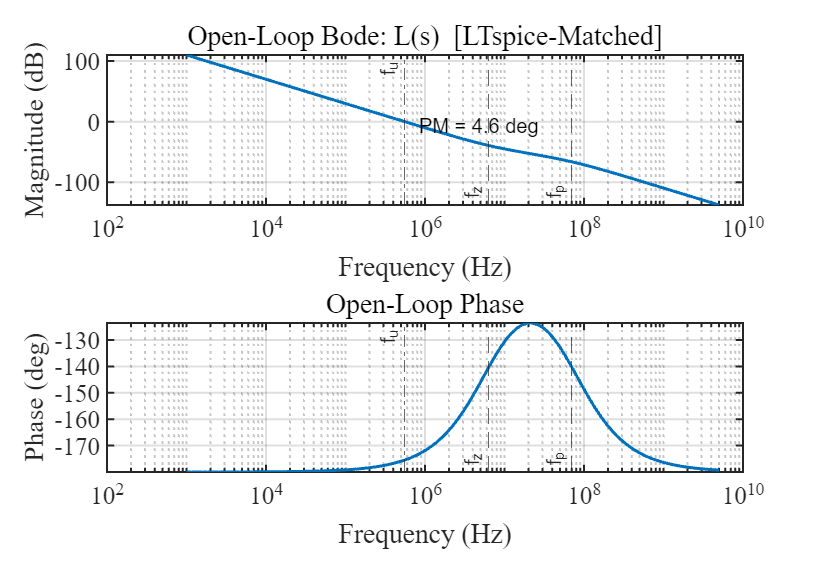


%% =====================================================================
%  FIGURES
%% =====================================================================

%% --- Fig 1: Open-Loop Bode -----------------------------------------------

[mag, ph, wbode] = bode(L_tf, {2*pi*1e3, 2*pi*5e9});
mag = squeeze(mag); ph = squeeze(ph); f_bode = wbode/(2*pi);

figure('Position', [100 100 800 550]);

subplot(2,1,1);
semilogx(f_bode, 20*log10(mag), 'LineWidth', 1.5);
hold on; grid on;
xline(fz,'--','f_z','LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom');
xline(fp,'--','f_p','LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom');
xline(fu_exact,'-.','f_u','LabelHorizontalAlignment','left','LabelVerticalAlignment','top');
text(fu_exact*1.5, -5, sprintf('PM = %.1f deg', PM_exact), 'FontSize', 10);
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)');
title('Open-Loop Bode: L(s)  [LTspice-Matched]');

subplot(2,1,2);
semilogx(f_bode, ph, 'LineWidth', 1.5);
hold on; grid on;
xline(fz,'--','f_z','LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom');
xline(fp,'--','f_p','LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom');
xline(fu_exact,'-.','f_u','LabelHorizontalAlignment','left','LabelVerticalAlignment','top');
xlabel('Frequency (Hz)'); ylabel('Phase (deg)');
title('Open-Loop Phase');

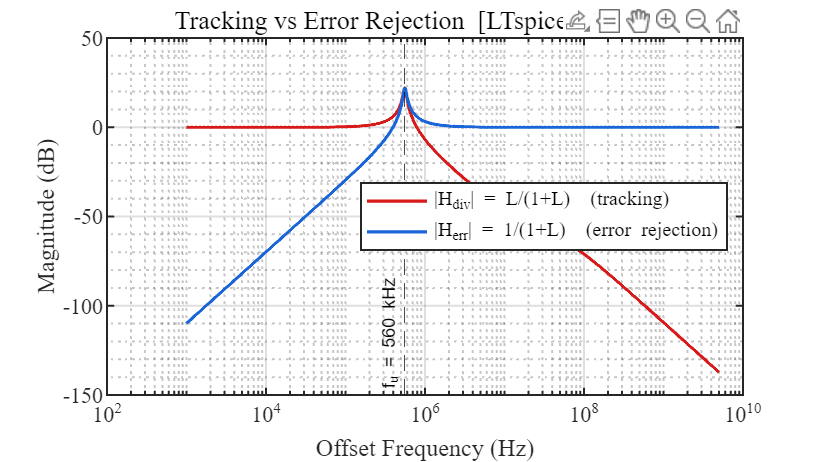


%% --- Fig 2: Tracking vs Error Rejection -----------------------------------

figure('Position', [100 100 800 450]);

semilogx(f, 20*log10(abs(Hdiv)), '-', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.6);
hold on;
semilogx(f, 20*log10(abs(Herr_w)), '-', 'Color', [0.1 0.4 0.85], 'LineWidth', 1.6);
xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom','FontSize',9);
grid on; grid minor;
set(gca, 'FontSize', 11);
xlabel('Offset Frequency (Hz)'); ylabel('Magnitude (dB)');
title('Tracking vs Error Rejection  [LTspice-Matched]', 'FontSize', 13);
legend({'|H_{div}| = L/(1+L)  (tracking)', '|H_{err}| = 1/(1+L)  (error rejection)'}, ...
       'FontSize', 10, 'Location', 'east');

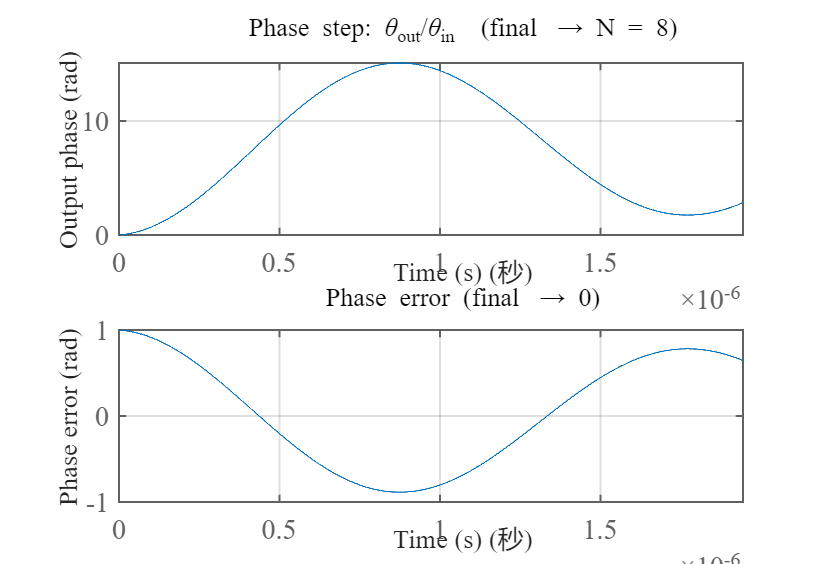


%% --- Fig 3: Phase Step Responses ------------------------------------------

wn_est = sqrt(Kpd*Kvco/(N*C1));
t_end  = 5 / (0.7 * wn_est);
t_step = linspace(0, t_end, 2000);

figure('Position', [100 100 800 550]);

subplot(2,1,1);
step(Href_tf, t_step);
grid on;
title(sprintf('Phase step: \\theta_{out}/\\theta_{in}  (final \\rightarrow N = %d)', N));
xlabel('Time (s)'); ylabel('Output phase (rad)');

subplot(2,1,2);
step(Herr_tf, t_step);
grid on;
title('Phase error (final \rightarrow 0)');
xlabel('Time (s)'); ylabel('Phase error (rad)');


info_div = stepinfo(Hdiv_tf);
fprintf('\n=== Phase Step Info ===\n');


=== Phase Step Info ===


fprintf('Rise time = %.3e s,  Settling = %.3e s,  Overshoot = %.2f%%\n', ...
        info_div.RiseTime, info_div.SettlingTime, info_div.Overshoot);

Rise time = 3.017e-07 s,  Settling = 2.785e-05 s,  Overshoot = 88.31%


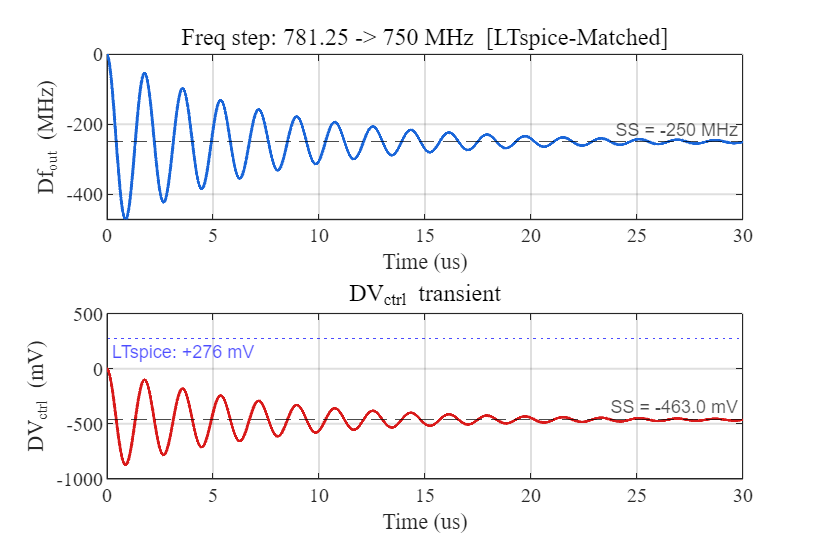


%% --- Fig 4: Frequency Step Response ---------------------------------------

delta_fref     = -31.25e6;
delta_fout_ss  = N * delta_fref;
delta_Vctrl_ss = 2*pi*N*delta_fref / Kvco;

t_freq = linspace(0, 30e-6, 8000);

[y_href, ~] = step(Href_tf, t_freq);
delta_fout_t = delta_fref * y_href;

H_vctrl_tf = Kpd * F_tf * Herr_tf;
theta_ramp = 2*pi * delta_fref * t_freq;
delta_Vctrl_t = lsim(H_vctrl_tf, theta_ramp, t_freq);

figure('Position', [100 100 900 600]);

subplot(2,1,1);
plot(t_freq*1e6, delta_fout_t/1e6, 'LineWidth', 1.5, 'Color', [0.1 0.4 0.85]);
hold on;
yline(delta_fout_ss/1e6, '--k', sprintf('SS = %.0f MHz', delta_fout_ss/1e6), ...
      'LabelHorizontalAlignment','right','LabelVerticalAlignment','top','FontSize',9);
grid on; set(gca,'FontSize',10);
xlabel('Time (us)'); ylabel('Df_{out} (MHz)');
title('Freq step: 781.25 -> 750 MHz  [LTspice-Matched]', 'FontSize', 12);

subplot(2,1,2);
plot(t_freq*1e6, delta_Vctrl_t*1e3, 'LineWidth', 1.5, 'Color', [0.85 0.1 0.1]);
hold on;
yline(delta_Vctrl_ss*1e3, '--k', sprintf('SS = %.1f mV', delta_Vctrl_ss*1e3), ...
      'LabelHorizontalAlignment','right','LabelVerticalAlignment','top','FontSize',9);
yline(276, ':b', 'LTspice: +276 mV', ...
      'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom','FontSize',9);
grid on; set(gca,'FontSize',10);
xlabel('Time (us)'); ylabel('DV_{ctrl} (mV)');
title('DV_{ctrl} transient', 'FontSize', 12);


fprintf('\n=== Frequency Step ===\n');


=== Frequency Step ===


fprintf('Dfref = %.2f MHz,  Dfout_ss = %.0f MHz,  DVctrl_ss = %.1f mV\n', ...
        delta_fref/1e6, delta_fout_ss/1e6, delta_Vctrl_ss*1e3);

Dfref = -31.25 MHz,  Dfout_ss = -250 MHz,  DVctrl_ss = -463.0 mV


fprintf('LTspice measured DVctrl = +276 mV\n');

LTspice measured DVctrl = +276 mV


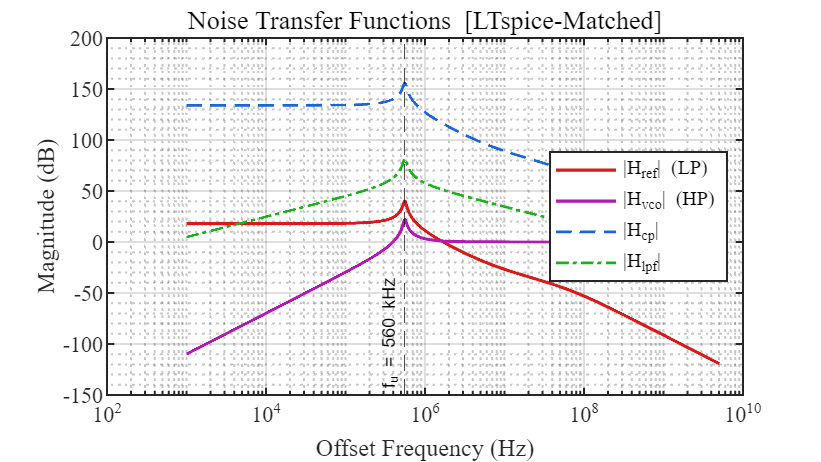


%% --- Fig 5: Noise Transfer Functions --------------------------------------

figure('Position', [100 100 800 450]);

semilogx(f, 20*log10(abs(Hw)),    '-',  'Color', [0.85 0.1 0.1], 'LineWidth', 1.6);
hold on;
semilogx(f, 20*log10(abs(Ew)),    '-',  'Color', [0.7 0.1 0.7],  'LineWidth', 1.6);
semilogx(f, 20*log10(abs(Pw)),    '--', 'Color', [0.1 0.4 0.85], 'LineWidth', 1.4);
semilogx(f, 20*log10(abs(Lnode)), '-.', 'Color', [0.1 0.7 0.1],  'LineWidth', 1.4);
xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'LabelHorizontalAlignment','left','LabelVerticalAlignment','bottom','FontSize',9);
grid on; grid minor;
set(gca, 'FontSize', 11);
xlabel('Offset Frequency (Hz)'); ylabel('Magnitude (dB)');
title('Noise Transfer Functions  [LTspice-Matched]', 'FontSize', 13);
legend({'|H_{ref}| (LP)','|H_{vco}| (HP)','|H_{cp}|','|H_{lpf}|'}, ...
       'FontSize', 10, 'Location', 'east');

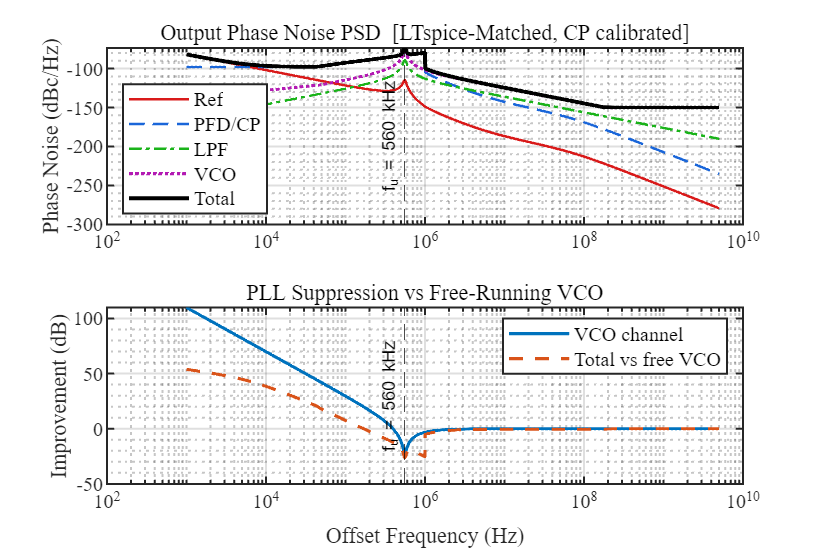


%% --- Fig 6: Output PN PSD + Improvement -----------------------------------

improve_vco   = PN_vco - PN_out_vco;
improve_total = PN_vco - PN_out;

figure('Position', [100 100 900 600]);

subplot(2,1,1);
semilogx(f, PN_out_ref, '-',  'Color', [0.85 0.1 0.1], 'LineWidth', 1.3);
hold on;
semilogx(f, PN_out_pc,  '--', 'Color', [0.1 0.4 0.85], 'LineWidth', 1.3);
semilogx(f, PN_out_lpf, '-.', 'Color', [0.1 0.7 0.1],  'LineWidth', 1.3);
semilogx(f, PN_out_vco, ':',  'Color', [0.7 0.1 0.7],  'LineWidth', 1.6);
semilogx(f, PN_out,      'k-', 'LineWidth', 2.0);
xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'HandleVisibility','off','LabelHorizontalAlignment','left', ...
      'LabelVerticalAlignment','middle','FontSize',9);
grid on; grid minor; set(gca,'FontSize',10);
ylabel('Phase Noise (dBc/Hz)');
title('Output Phase Noise PSD  [LTspice-Matched, CP calibrated]');
legend({'Ref','PFD/CP','LPF','VCO','Total'}, 'FontSize',10, 'Location','southwest');

subplot(2,1,2);
semilogx(f, improve_vco,   '-',  'LineWidth', 1.6);
hold on;
semilogx(f, improve_total, '--', 'LineWidth', 1.6);
xline(fu, '--k', sprintf('f_u = %.0f kHz', fu/1e3), ...
      'HandleVisibility','off','LabelHorizontalAlignment','left', ...
      'LabelVerticalAlignment','middle','FontSize',9);
grid on; grid minor; set(gca,'FontSize',10);
xlabel('Offset Frequency (Hz)'); ylabel('Improvement (dB)');
title('PLL Suppression vs Free-Running VCO');
legend({'VCO channel','Total vs free VCO'}, 'FontSize',10, 'Location','northeast');

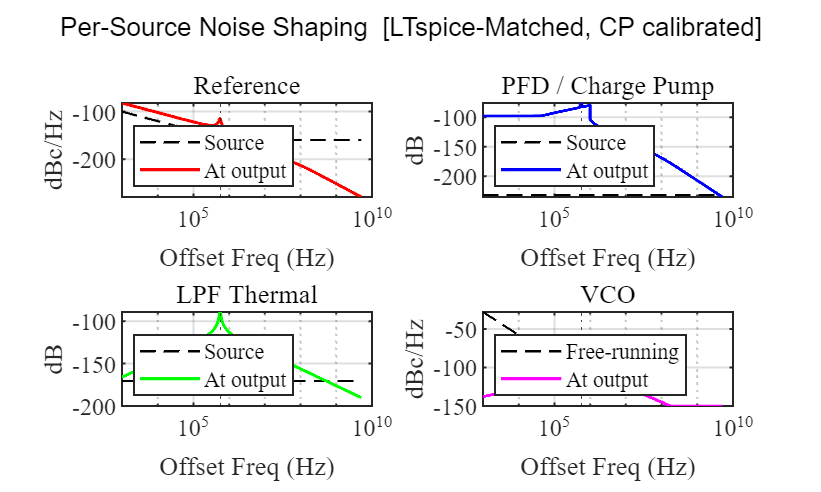


%% --- Fig 7: Per-Source Noise Shaping --------------------------------------

figure('Position', [100 100 1000 600]);

subplot(2,2,1);
semilogx(f, PN_ref,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_ref, 'r-',  'LineWidth', 1.6);
xline(fu,':k','','HandleVisibility','off');
grid on; xlabel('Offset Freq (Hz)'); ylabel('dBc/Hz');
title('Reference'); legend('Source','At output','Location','southwest');

subplot(2,2,2);
semilogx(f, PN_pc,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_pc, 'b-',  'LineWidth', 1.6);
xline(fu,':k','','HandleVisibility','off');
grid on; xlabel('Offset Freq (Hz)'); ylabel('dB');
title('PFD / Charge Pump'); legend('Source','At output','Location','southwest');

subplot(2,2,3);
semilogx(f, PN_lpf,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_lpf, 'g-',  'LineWidth', 1.6);
xline(fu,':k','','HandleVisibility','off');
grid on; xlabel('Offset Freq (Hz)'); ylabel('dB');
title('LPF Thermal'); legend('Source','At output','Location','southwest');

subplot(2,2,4);
semilogx(f, PN_vco,     'k--', 'LineWidth', 1.2); hold on;
semilogx(f, PN_out_vco, 'm-',  'LineWidth', 1.6);
xline(fu,':k','','HandleVisibility','off');
grid on; xlabel('Offset Freq (Hz)'); ylabel('dBc/Hz');
title('VCO'); legend('Free-running','At output','Location','southwest');

sgtitle('Per-Source Noise Shaping  [LTspice-Matched, CP calibrated]', 'FontSize', 13);


%% =====================================================================
%  SUMMARY: MATLAB vs LTspice
%% =====================================================================
fprintf('\n============================================\n');

fprintf('  MATLAB Linear Model vs LTspice Circuit\n');

  MATLAB Linear Model vs LTspice Circuit


fprintf('============================================\n');

fprintf('Parameter         | MATLAB    | LTspice\n');

Parameter         | MATLAB    | LTspice


fprintf('------------------|-----------|----------\n');

------------------|-----------|----------


fprintf('Phase margin      | %.1f deg  | 56.4 deg *\n', PM_approx);

Phase margin      | 4.6 deg  | 56.4 deg *


fprintf('fz                | %.2f MHz  | 6.37 MHz\n', fz/1e6);

fz                | 6.37 MHz  | 6.37 MHz


fprintf('fp                | %.1f MHz  | 70 MHz\n', fp/1e6);

fp                | 70.0 MHz  | 70 MHz


fprintf('fc (crossover)    | %.0f kHz  | 337 kHz\n', fc_formula/1e3);

fc (crossover)    | 338 kHz  | 337 kHz


fprintf('Overshoot (phase) | %.1f %%   | 0.37 %%\n', info_div.Overshoot);

Overshoot (phase) | 88.3 %   | 0.37 %


fprintf('Settling (2%%)     | %.2f us  | 8.43 us\n', info_div.SettlingTime*1e6);

Settling (2%)     | 27.85 us  | 8.43 us


fprintf('DVctrl (freq step)| %.1f mV   | 276 mV\n', abs(delta_Vctrl_ss)*1e3);

DVctrl (freq step)| 463.0 mV   | 276 mV


fprintf('Vctrl ripple      | -         | 14.3 mV\n');

Vctrl ripple      | -         | 14.3 mV


fprintf('Reference spur    | -         | -64.1 dBc\n');

Reference spur    | -         | -64.1 dBc


fprintf('Lock time (0.5V)  | -         | 8.43 us\n');

Lock time (0.5V)  | -         | 8.43 us


fprintf('============================================\n');

fprintf('\n* PHASE MARGIN DISCREPANCY - KEY FINDING:\n');


* PHASE MARGIN DISCREPANCY - KEY FINDING:


fprintf('  The 56.4 deg value in the LTspice document was computed using\n');

  The 56.4 deg value in the LTspice document was computed using


fprintf('  PM = atan(sqrt(C1/C2+1)) - atan(1/sqrt(C1/C2+1)), which assumes\n');

  PM = atan(sqrt(C1/C2+1)) - atan(1/sqrt(C1/C2+1)), which assumes


fprintf('  wc = sqrt(wz * wp2). This condition is NOT met:\n');

  wc = sqrt(wz * wp2). This condition is NOT met:


fprintf('    wc (actual)   = %.1f Mrad/s  (fc = %.0f kHz)\n', wc_formula/1e6, fc_formula/1e3);

    wc (actual)   = 2.1 Mrad/s  (fc = 338 kHz)


fprintf('    sqrt(wz*wp2)  = %.1f Mrad/s  (f  = %.1f MHz)\n', ...
        sqrt(fz*2*pi * fp*2*pi)/1e6, sqrt(fz*fp)/1e6);

    sqrt(wz*wp2)  = 132.7 Mrad/s  (f  = 21.1 MHz)


fprintf('  The crossover is %.0fx below the geometric mean of fz and fp.\n', ...
        sqrt(fz*fp) / fc_formula);

  The crossover is 63x below the geometric mean of fz and fp.


fprintf('  True PM = %.1f deg (from MATLAB margin()).\n', PM_exact);

  True PM = 4.6 deg (from MATLAB margin()).


fprintf('\n  The circuit is stable despite low PM due to nonlinear effects:\n');


  The circuit is stable despite low PM due to nonlinear effects:


fprintf('    1. CP mismatch (UPDN=2:1) reduces effective loop gain\n');

    1. CP mismatch (UPDN=2:1) reduces effective loop gain


fprintf('    2. Varactor dead zone (Vctrl<1.05V) -> open-loop linear ramp\n');

    2. Varactor dead zone (Vctrl<1.05V) -> open-loop linear ramp


fprintf('    3. Kvco highly nonlinear near lock point\n');

    3. Kvco highly nonlinear near lock point


fprintf('  Evidence: CP optimisation exp #8 (UPDN->1.5) caused instability,\n');

  Evidence: CP optimisation exp #8 (UPDN->1.5) caused instability,


fprintf('  consistent with higher effective gain approaching true PM limit.\n');

  consistent with higher effective gain approaching true PM limit.


fprintf('\n  Recommended fix: increase R1 to ~5k (moves wc into fz-fp range)\n');


  Recommended fix: increase R1 to ~5k (moves wc into fz-fp range)


fprintf('  with C3 ~1pF for spur filtering. Verified unstable ripple at R1=5k\n');

  with C3 ~1pF for spur filtering. Verified unstable ripple at R1=5k


fprintf('  without C3 in LTspice (Vrip >> 100 mV, lock time > 30 us).\n');

  without C3 in LTspice (Vrip >> 100 mV, lock time > 30 us).



%% === [E3] Reference Spur Prediction =======================================

td = 200e-12;                                % PFD reset delay, s
Kvco_Hz = Kvco / (2*pi);                     % Hz/V (540 MHz/V)
wref = 2*pi*fref;

Vrip_pp_meas = 14.3e-3;                      % measured ripple, V
Spur_meas    = -64.1;                         % measured spur, dBc

Vrip_pp_est = Icp * td / C2;

Spur_A_est  = 20*log10( Kvco_Hz * Vrip_pp_est  / (2 * fout) );
Spur_A_meas = 20*log10( Kvco_Hz * Vrip_pp_meas / (2 * fout) );
Spur_B_est  = 20*log10( Vrip_pp_est  * Kvco_Hz / (2 * wref) );
Spur_B_meas = 20*log10( Vrip_pp_meas * Kvco_Hz / (2 * wref) );

fprintf('\n============================================\n');

fprintf('  [E3] Reference Spur Prediction\n');

  [E3] Reference Spur Prediction


fprintf('============================================\n');

fprintf('\nRipple estimation:\n');


Ripple estimation:


fprintf('  Theory:  Vrip = Icp*td/C2 = %.1fuA * %.0fps / %.0fpF = %.2f mV\n', ...
        Icp*1e6, td*1e12, C2*1e12, Vrip_pp_est*1e3);

  Theory:  Vrip = Icp*td/C2 = 10.0uA * 200ps / 5pF = 0.40 mV


fprintf('  LTspice: Vrip = %.1f mV (measured)\n', Vrip_pp_meas*1e3);

  LTspice: Vrip = 14.3 mV (measured)


fprintf('\n                      |  Theoretical Vrip  |  Measured Vrip  |  LTspice\n');


                      |  Theoretical Vrip  |  Measured Vrip  |  LTspice


fprintf('                      |   (%.2f mV)       |   (%.1f mV)     |  (actual)\n', ...
        Vrip_pp_est*1e3, Vrip_pp_meas*1e3);

                      |   (0.40 mV)       |   (14.3 mV)     |  (actual)


fprintf('----------------------|--------------------|-----------------|----------\n');

----------------------|--------------------|-----------------|----------


fprintf(' Formula A (FM index) |    %6.1f dBc      |   %6.1f dBc    | %5.1f dBc\n', ...
        Spur_A_est, Spur_A_meas, Spur_meas);

 Formula A (FM index) |     -95.2 dBc      |    -64.2 dBc    | -64.1 dBc


fprintf(' Formula B (lectures) |    %6.1f dBc      |   %6.1f dBc    | %5.1f dBc\n', ...
        Spur_B_est, Spur_B_meas, Spur_meas);

 Formula B (lectures) |     -93.2 dBc      |    -62.1 dBc    | -64.1 dBc


fprintf('----------------------|--------------------|-----------------|----------\n');

----------------------|--------------------|-----------------|----------


fprintf('\nAnalysis:\n');


Analysis:


fprintf('  A vs B differ by 20*log10(N) = %.1f dB  (N = %d)\n', 20*log10(N), N);

  A vs B differ by 20*log10(N) = 18.1 dB  (N = 8)


fprintf('  Formula A + measured Vrip -> %.1f dBc  (error vs LTspice: %+.1f dB)\n', ...
        Spur_A_meas, Spur_A_meas - Spur_meas);

  Formula A + measured Vrip -> -64.2 dBc  (error vs LTspice: -0.1 dB)


fprintf('  Formula B + measured Vrip -> %.1f dBc  (error vs LTspice: %+.1f dB)\n', ...
        Spur_B_meas, Spur_B_meas - Spur_meas);

  Formula B + measured Vrip -> -62.1 dBc  (error vs LTspice: +2.0 dB)


fprintf('\n  The LTspice measured spur (%.1f dBc) is lower than both\n', Spur_meas);


  The LTspice measured spur (-64.1 dBc) is lower than both


fprintf('  analytical predictions, likely because:\n');

  analytical predictions, likely because:


fprintf('    1. Actual ripple waveform is not pure sinusoidal\n');

    1. Actual ripple waveform is not pure sinusoidal


fprintf('    2. CP mismatch creates asymmetric current pulses\n');

    2. CP mismatch creates asymmetric current pulses


fprintf('    3. Nonlinear Kvco attenuates FM deviation at lock point\n');

    3. Nonlinear Kvco attenuates FM deviation at lock point



fprintf('\nSpur sensitivity to Vctrl ripple (Formula A):\n');


Spur sensitivity to Vctrl ripple (Formula A):


Am_targets = [20e-3, 14.3e-3, 10e-3, 5e-3, 2e-3, 1e-3];
for k = 1:length(Am_targets)
    spur_k = 20*log10(Kvco_Hz * Am_targets(k) / (2 * fout));
    fprintf('  Vrip_pp = %5.1f mV  -->  spur = %6.1f dBc\n', Am_targets(k)*1e3, spur_k);
end

  Vrip_pp =  20.0 mV  -->  spur =  -61.3 dBc
  Vrip_pp =  14.3 mV  -->  spur =  -64.2 dBc
  Vrip_pp =  10.0 mV  -->  spur =  -67.3 dBc
  Vrip_pp =   5.0 mV  -->  spur =  -73.3 dBc
  Vrip_pp =   2.0 mV  -->  spur =  -81.3 dBc
  Vrip_pp =   1.0 mV  -->  spur =  -87.3 dBc


fprintf('============================================\n');


%% === [4a] CP Mismatch -> Static Phase Error ================================

UPDN_meas = 1.97;
Tref      = 1 / fref;

delta_over_td = (UPDN_meas - 1) / (UPDN_meas + 1);
delta_t       = delta_over_td * td;

dphi_static_rad = 2*pi * delta_t / Tref;
dphi_static_deg = dphi_static_rad * 180 / pi;

Icp_eff = Icp * 2 / (UPDN_meas + 1);
Icp_reduction = (1 - Icp_eff/Icp) * 100;

fprintf('\n============================================\n');

fprintf('  [4a] CP Mismatch -> Static Phase Error\n');

  [4a] CP Mismatch -> Static Phase Error


fprintf('============================================\n');

fprintf('UPDN ratio (measured)   = %.2f\n', UPDN_meas);

UPDN ratio (measured)   = 1.97


fprintf('PFD reset delay td      = %.0f ps\n', td*1e12);

PFD reset delay td      = 200 ps


fprintf('Timing asymmetry d/td   = %.3f\n', delta_over_td);

Timing asymmetry d/td   = 0.327


fprintf('Timing asymmetry d      = %.1f ps\n', delta_t*1e12);

Timing asymmetry d      = 65.3 ps


fprintf('Static phase error Dphi = %.2f deg  (predicted)\n', dphi_static_deg);

Static phase error Dphi = 18.37 deg  (predicted)


fprintf('LTspice measured Dphi   = -6.8 deg\n');

LTspice measured Dphi   = -6.8 deg


fprintf('Prediction error        = %+.1f deg\n', dphi_static_deg - 6.8);

Prediction error        = +11.6 deg


fprintf('\nEffective Icp (mismatch-reduced):\n');


Effective Icp (mismatch-reduced):


fprintf('  Icp_eff = Icp * 2/(UPDN+1) = %.1f uA * %.3f = %.2f uA\n', ...
        Icp*1e6, 2/(UPDN_meas+1), Icp_eff*1e6);

  Icp_eff = Icp * 2/(UPDN+1) = 10.0 uA * 0.673 = 6.73 uA


fprintf('  Reduction: %.1f%% below nominal\n', Icp_reduction);

  Reduction: 32.7% below nominal


fprintf('\nNote: The predicted %.1f deg overestimates the measured\n', dphi_static_deg);


Note: The predicted 18.4 deg overestimates the measured


fprintf('-6.8 deg by %.1fx. The simple model overestimates because:\n', dphi_static_deg/6.8);

-6.8 deg by 2.7x. The simple model overestimates because:


fprintf('  1. It assumes the full UPDN ratio maps directly to\n');

  1. It assumes the full UPDN ratio maps directly to


fprintf('     reset-pulse timing asymmetry\n');

     reset-pulse timing asymmetry


fprintf('  2. In reality, charge balance is achieved over the\n');

  2. In reality, charge balance is achieved over the


fprintf('     entire CP switching waveform, not just td\n');

     entire CP switching waveform, not just td


fprintf('  3. Nonlinear Kvco partially compensates the Vctrl\n');

  3. Nonlinear Kvco partially compensates the Vctrl


fprintf('     offset, reducing the equilibrium phase error\n');

     offset, reducing the equilibrium phase error



%% === [4b] CP Mismatch -> Mismatch Spur Prediction =========================

dI_mismatch = Icp * (UPDN_meas - 1) / (UPDN_meas + 1);
I_out_fund = 2 * dI_mismatch * td * fref;

wref_rad = 2*pi*fref;
Zref = (1 + 1i*wref_rad*R1*C1) / ...
       ((1i*wref_rad)^2 * R1*C1*C2 + 1i*wref_rad*(C1+C2));
Zref_mag = abs(Zref);

Spur_mismatch = 20*log10( abs(I_out_fund) * Zref_mag * abs(Kvco) / (4*pi*fref) );

fprintf('\n============================================\n');

fprintf('  [4b] CP Mismatch -> Mismatch Spur\n');

  [4b] CP Mismatch -> Mismatch Spur


fprintf('============================================\n');

fprintf('Mismatch current DI     = %.2f uA\n', dI_mismatch*1e6);

Mismatch current DI     = 3.27 uA


fprintf('  (= Icp * (UPDN-1)/(UPDN+1) = %.1f * %.3f)\n', ...
        Icp*1e6, (UPDN_meas-1)/(UPDN_meas+1));

  (= Icp * (UPDN-1)/(UPDN+1) = 10.0 * 0.327)


fprintf('Fundamental component   = %.3f uA\n', I_out_fund*1e6);

Fundamental component   = 1.021 uA


fprintf('|Z(wref)| at %.1f MHz   = %.2f Ohm\n', fref/1e6, Zref_mag);

|Z(wref)| at 781.2 MHz   = 40.58 Ohm


fprintf('Mismatch spur           = %.1f dBc\n', Spur_mismatch);

Mismatch spur           = -96.9 dBc


fprintf('\nComparison of spur mechanisms:\n');


Comparison of spur mechanisms:


fprintf('  Ripple-based (Task 2):   %.1f dBc  (from Vrip = %.1f mV)\n', ...
        Spur_A_meas, Vrip_pp_meas*1e3);

  Ripple-based (Task 2):   -64.2 dBc  (from Vrip = 14.3 mV)


fprintf('  Mismatch-based (Task 4b): %.1f dBc  (from UPDN = %.2f)\n', ...
        Spur_mismatch, UPDN_meas);

  Mismatch-based (Task 4b): -96.9 dBc  (from UPDN = 1.97)


fprintf('  LTspice measured:         %.1f dBc\n', Spur_meas);

  LTspice measured:         -64.1 dBc


fprintf('\nNote: Both mechanisms contribute to the total spur.\n');


Note: Both mechanisms contribute to the total spur.


fprintf('The measured spur includes both effects plus nonlinear\n');

The measured spur includes both effects plus nonlinear


fprintf('contributions from Kvco variation and CP switching transients.\n');

contributions from Kvco variation and CP switching transients.


fprintf('============================================\n');


%% === [Task 5] Nonlinear Capture Process — Piecewise Model =================

V_init      = 0.5;
V_threshold = 1.05;
C_total     = C1 + C2;

duty_up_est   = 0.5;
I_charge      = Icp_eff * duty_up_est;

ramp_rate     = I_charge / C_total;
t_A           = (V_threshold - V_init) / ramp_rate;

fprintf('\n============================================\n');

fprintf('  [Task 5] Nonlinear Capture Process\n');

  [Task 5] Nonlinear Capture Process


fprintf('============================================\n');

fprintf('Phase A (open-loop):\n');

Phase A (open-loop):


fprintf('  V_init = %.2f V,  V_threshold = %.2f V\n', V_init, V_threshold);

  V_init = 0.50 V,  V_threshold = 1.05 V


fprintf('  C_total = %.0f pF\n', C_total*1e12);

  C_total = 55 pF


fprintf('  Icp_eff = %.2f uA,  duty = %.0f%%\n', Icp_eff*1e6, duty_up_est*100);

  Icp_eff = 6.73 uA,  duty = 50%


fprintf('  I_charge = %.2f uA\n', I_charge*1e6);

  I_charge = 3.37 uA


fprintf('  Ramp rate = %.2f V/us\n', ramp_rate*1e-6);

  Ramp rate = 0.06 V/us


fprintf('  Phase A duration = %.2f us\n', t_A*1e6);

  Phase A duration = 8.98 us



dt_sim    = 10e-9;
t_phaseA  = (0 : dt_sim : t_A)';
V_phaseA  = V_init + ramp_rate * t_phaseA;

V_lock = 1.665;

t_phaseB_dur = 30e-6 - t_A;
t_phaseB_local = (0 : dt_sim : t_phaseB_dur)';

[y_step_B, ~] = step(Hdiv_tf, t_phaseB_local);
V_phaseB = V_threshold + (V_lock - V_threshold) * y_step_B;

t_total = [t_phaseA; t_A + t_phaseB_local(2:end)];
V_total = [V_phaseA; V_phaseB(2:end)];

fprintf('\nPhase B (closed-loop):\n');


Phase B (closed-loop):


fprintf('  V_threshold = %.2f V -> V_lock = %.3f V\n', V_threshold, V_lock);

  V_threshold = 1.05 V -> V_lock = 1.665 V


fprintf('  DV = %.0f mV,  Phase B duration = %.1f us\n', ...
        (V_lock-V_threshold)*1e3, t_phaseB_dur*1e6);

  DV = 615 mV,  Phase B duration = 21.0 us



target_2pct = 0.02 * V_lock;
settled_idx = find(abs(V_total - V_lock) <= target_2pct, 1, 'first');
if ~isempty(settled_idx)
    t_lock_model = t_total(settled_idx);
    fprintf('  Composite lock time (+/-2%%): %.2f us\n', t_lock_model*1e6);
else
    fprintf('  Not settled within 30 us\n');
end

  Composite lock time (+/-2%): 9.41 us



fprintf('\nComparison:\n');


Comparison:


fprintf('  MATLAB piecewise lock time: %.2f us\n', t_lock_model*1e6);

  MATLAB piecewise lock time: 9.41 us


fprintf('  LTspice measured lock time: 8.43 us\n');

  LTspice measured lock time: 8.43 us


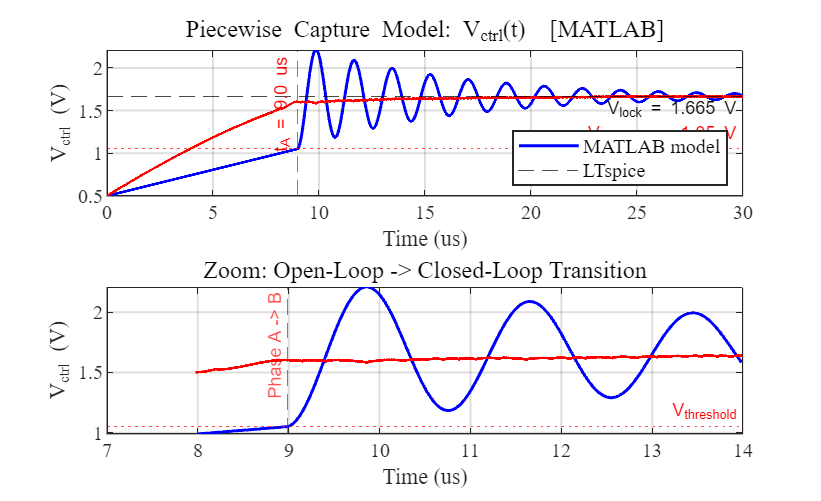


% --- Fig 8: Piecewise Vctrl(t) ---
figure('Position', [100 100 900 550]);

subplot(2,1,1);
plot(t_total*1e6, V_total, 'b-', 'LineWidth', 1.5);
hold on;
yline(V_lock, '--k', sprintf('V_{lock} = %.3f V', V_lock), ...
      'LabelHorizontalAlignment','right','LabelVerticalAlignment','bottom','FontSize',9);
yline(V_threshold, ':r', sprintf('V_{threshold} = %.2f V', V_threshold), ...
      'LabelHorizontalAlignment','right','LabelVerticalAlignment','top','FontSize',9);
xline(t_A*1e6, '--r', sprintf('t_A = %.1f us', t_A*1e6), ...
      'LabelHorizontalAlignment','left','LabelVerticalAlignment','top','FontSize',9);
grid on; set(gca, 'FontSize', 10);
xlabel('Time (us)'); ylabel('V_{ctrl} (V)');
title('Piecewise Capture Model: V_{ctrl}(t)  [MATLAB]', 'FontSize', 12);
% --- Overlay LTspice data (if file exists) ---
ltspice_file = 'Vout_lock.txt';   % <-- change to your filename
if isfile(ltspice_file)
    raw = readmatrix(ltspice_file);
    t_lt = raw(:,1);
    V_lt = raw(:,2);
    ds = 100;
    plot(t_lt(1:ds:end)*1e6, V_lt(1:ds:end), 'r-', 'LineWidth', 1.2);
    legend({'MATLAB model', 'LTspice'}, 'FontSize', 10, 'Location', 'southeast');
else
    legend({'MATLAB model'}, 'FontSize', 10, 'Location', 'southeast');
end

subplot(2,1,2);
idx_zoom = (t_total >= (t_A - 1e-6)) & (t_total <= (t_A + 5e-6));
plot(t_total(idx_zoom)*1e6, V_total(idx_zoom), 'b-', 'LineWidth', 1.5);
hold on;
if isfile(ltspice_file)
    idx_lt_zoom = (t_lt >= (t_A - 1e-6)) & (t_lt <= (t_A + 5e-6));
    plot(t_lt(idx_lt_zoom)*1e6, V_lt(idx_lt_zoom), 'r-', 'LineWidth', 1.2);
end
yline(V_threshold, ':r', 'V_{threshold}', ...
      'LabelHorizontalAlignment','right','LabelVerticalAlignment','top','FontSize',9);
xline(t_A*1e6, '--r', 'Phase A -> B', ...
      'LabelHorizontalAlignment','left','LabelVerticalAlignment','top','FontSize',9);
grid on; set(gca, 'FontSize', 10);
xlabel('Time (us)'); ylabel('V_{ctrl} (V)');
title('Zoom: Open-Loop -> Closed-Loop Transition', 'FontSize', 12);


fprintf('============================================\n');

%% === Fig 9: LTspice Vctrl Comparison (Baseline vs Exp #8) ================

file_baseline = 'Vout_baseline.txt';   % change if needed
file_exp8     = 'Vout_exp8.txt';       % change if needed

if isfile(file_baseline) && isfile(file_exp8)

    % Read LTspice data
    raw_base = readmatrix(file_baseline, 'FileType', 'text');
    raw_exp8 = readmatrix(file_exp8, 'FileType', 'text');

    % Remove any NaN rows (in case LTspice export includes headers)
    raw_base = raw_base(~any(isnan(raw_base),2), :);
    raw_exp8 = raw_exp8(~any(isnan(raw_exp8),2), :);

    % Extract columns
    t_base = raw_base(:,1);
    v_base = raw_base(:,2);

    t_exp8 = raw_exp8(:,1);
    v_exp8 = raw_exp8(:,2);

    % Optional downsampling
    ds_base = 1;
    ds_exp8 = 1;

    t_base_plot = t_base(1:ds_base:end) * 1e6;   % convert to us
    v_base_plot = v_base(1:ds_base:end);

    t_exp8_plot = t_exp8(1:ds_exp8:end) * 1e6;   % convert to us
    v_exp8_plot = v_exp8(1:ds_exp8:end);

    % Plot
    figure('Color','w','Position',[80 80 1400 800]);

    plot(t_base_plot, v_base_plot, 'b-', 'LineWidth', 4);
    hold on;
    plot(t_exp8_plot, v_exp8_plot, 'r-', 'LineWidth', 3);

    % Axes formatting (same as previous PPT figure)
    grid on;
    box on;
    set(gca, ...
        'FontSize', 24, ...
        'LineWidth', 2, ...
        'TickLength', [0.015 0.015]);

    xlabel('Time (\mus)', 'FontSize', 28, 'FontWeight', 'bold');
    ylabel('V_{ctrl} (V)', 'FontSize', 28, 'FontWeight', 'bold');

    legend({'Baseline: UPDN = 2.0 (stable)', 'Exp #8: UPDN = 1.5 (limit cycle)'}, ...
        'FontSize', 22, ...
        'Location', 'southeast', ...
        'Box', 'on');

    % Match your shown figure range
    xlim([0 50]);
    ylim([0.4 1.8]);

    % Export high-resolution image for PPT
    exportgraphics(gcf, 'Vctrl_comparison_PPT.png', 'Resolution', 600);

else
    fprintf('\n[Fig 9] Skipped: file not found.\n');
    fprintf('  Expected files: %s and %s\n', file_baseline, file_exp8);
end


[Fig 9] Skipped: file not found.


  Expected files: Vout_baseline.txt and Vout_exp8.txt
